%% ================================================================
%  ANÁLISE E TRANSFORMAÇÃO DE DADOS – PROJETO 2026
%  Meta 1 – Pontos 1 ao 13
%
%  Estrutura esperada:
%    data/
%      01/
%        0_01_0.wav   <- digito=0, participante=01, repeticao=0
%        ...
%
%  IMPORTANTE: coloque este script na mesma pasta onde está a pasta data/
%  As funções locais estão no FINAL deste ficheiro (obrigatório MATLAB).
% ================================================================

clear; clc; close all;

% Pasta do participante escolhido pelo grupo (alterar conforme necessário)
DATA_PATH = fullfile('data', '01');

%% ================================================================
%  PONTO 1 – Criação da Estrutura de Dados
% ================================================================
fprintf('=== PONTO 1: Criação da estrutura de dados ===\n');

=== PONTO 1: Criação da estrutura de dados ===



if ~isfolder(DATA_PATH)
    error('Pasta "%s" não encontrada. Ajuste a variável DATA_PATH.', DATA_PATH);
end

% fullfile: constrói o caminho 'data/01/*.wav'
% dir: lista todos os ficheiros .wav que correspondem ao padrão
wav_files = dir(fullfile(DATA_PATH, '*.wav'));
fprintf('Ficheiros encontrados: %d\n', numel(wav_files));

Ficheiros encontrados: 500



directory    = {};
filename_col = {};
participant  = [];
digit_col    = [];
repetition   = [];

for f = 1:numel(wav_files)
    fname = wav_files(f).name;
    parts = strsplit(fname(1:end-4), '_');

    directory{end+1,1}    = DATA_PATH;
    filename_col{end+1,1} = fname;
    digit_col(end+1,1)    = str2double(parts{1});
    participant(end+1,1)  = str2double(parts{2});
    repetition(end+1,1)   = str2double(parts{3});
end

T = table(directory, filename_col, participant, digit_col, repetition, ...
    'VariableNames',{'Directory','Filename','Participant','Digit','Repetition'});
T = sortrows(T, {'Digit','Repetition'});

fprintf('Total de ficheiros  : %d\n',   height(T));

Total de ficheiros  : 500


fprintf('Participante        : %d\n',   T.Participant(1));

Participante        : 1


fprintf('Dígitos             : %s\n',   num2str(unique(T.Digit)'));

Dígitos             : 0  1  2  3  4  5  6  7  8  9


fprintf('Repetições por díg. : %d\n\n', numel(unique(T.Repetition)));

Repetições por díg. : 50



disp(head(T, 5));

     Directory        Filename       Participant    Digit    Repetition
    ___________    ______________    ___________    _____    __________

    {'data/01'}    {'0_01_0.wav'}         1           0          0     
    {'data/01'}    {'0_01_1.wav'}         1           0          1     
    {'data/01'}    {'0_01_2.wav'}         1           0          2     
    {'data/01'}    {'0_01_3.wav'}         1           0          3     
    {'data/01'}    {'0_01_4.wav'}         1           0          4     




%% ================================================================
%  PONTO 2 – Importação dos Sinais de Áudio
% ================================================================

N_files      = height(T);
signals      = cell(N_files, 1);
sample_rates = zeros(N_files, 1);

for i = 1:N_files
    filepath        = fullfile(T.Directory{i}, T.Filename{i});
    [sig, fs]       = audioread(filepath);
    signals{i}      = double(sig);
    sample_rates(i) = fs;
end

T.SampleRate = sample_rates;
T.Signal     = signals;

durations = cellfun(@numel, signals) ./ sample_rates;
fprintf('Taxa de amostragem : %d Hz\n',    T.SampleRate(1));

Taxa de amostragem : 48000 Hz


fprintf('Duração mínima     : %.3f s\n',   min(durations));

Duração mínima     : 0.383 s


fprintf('Duração máxima     : %.3f s\n',   max(durations));

Duração máxima     : 0.916 s


fprintf('Duração média      : %.3f s\n\n', mean(durations));

Duração média      : 0.622 s



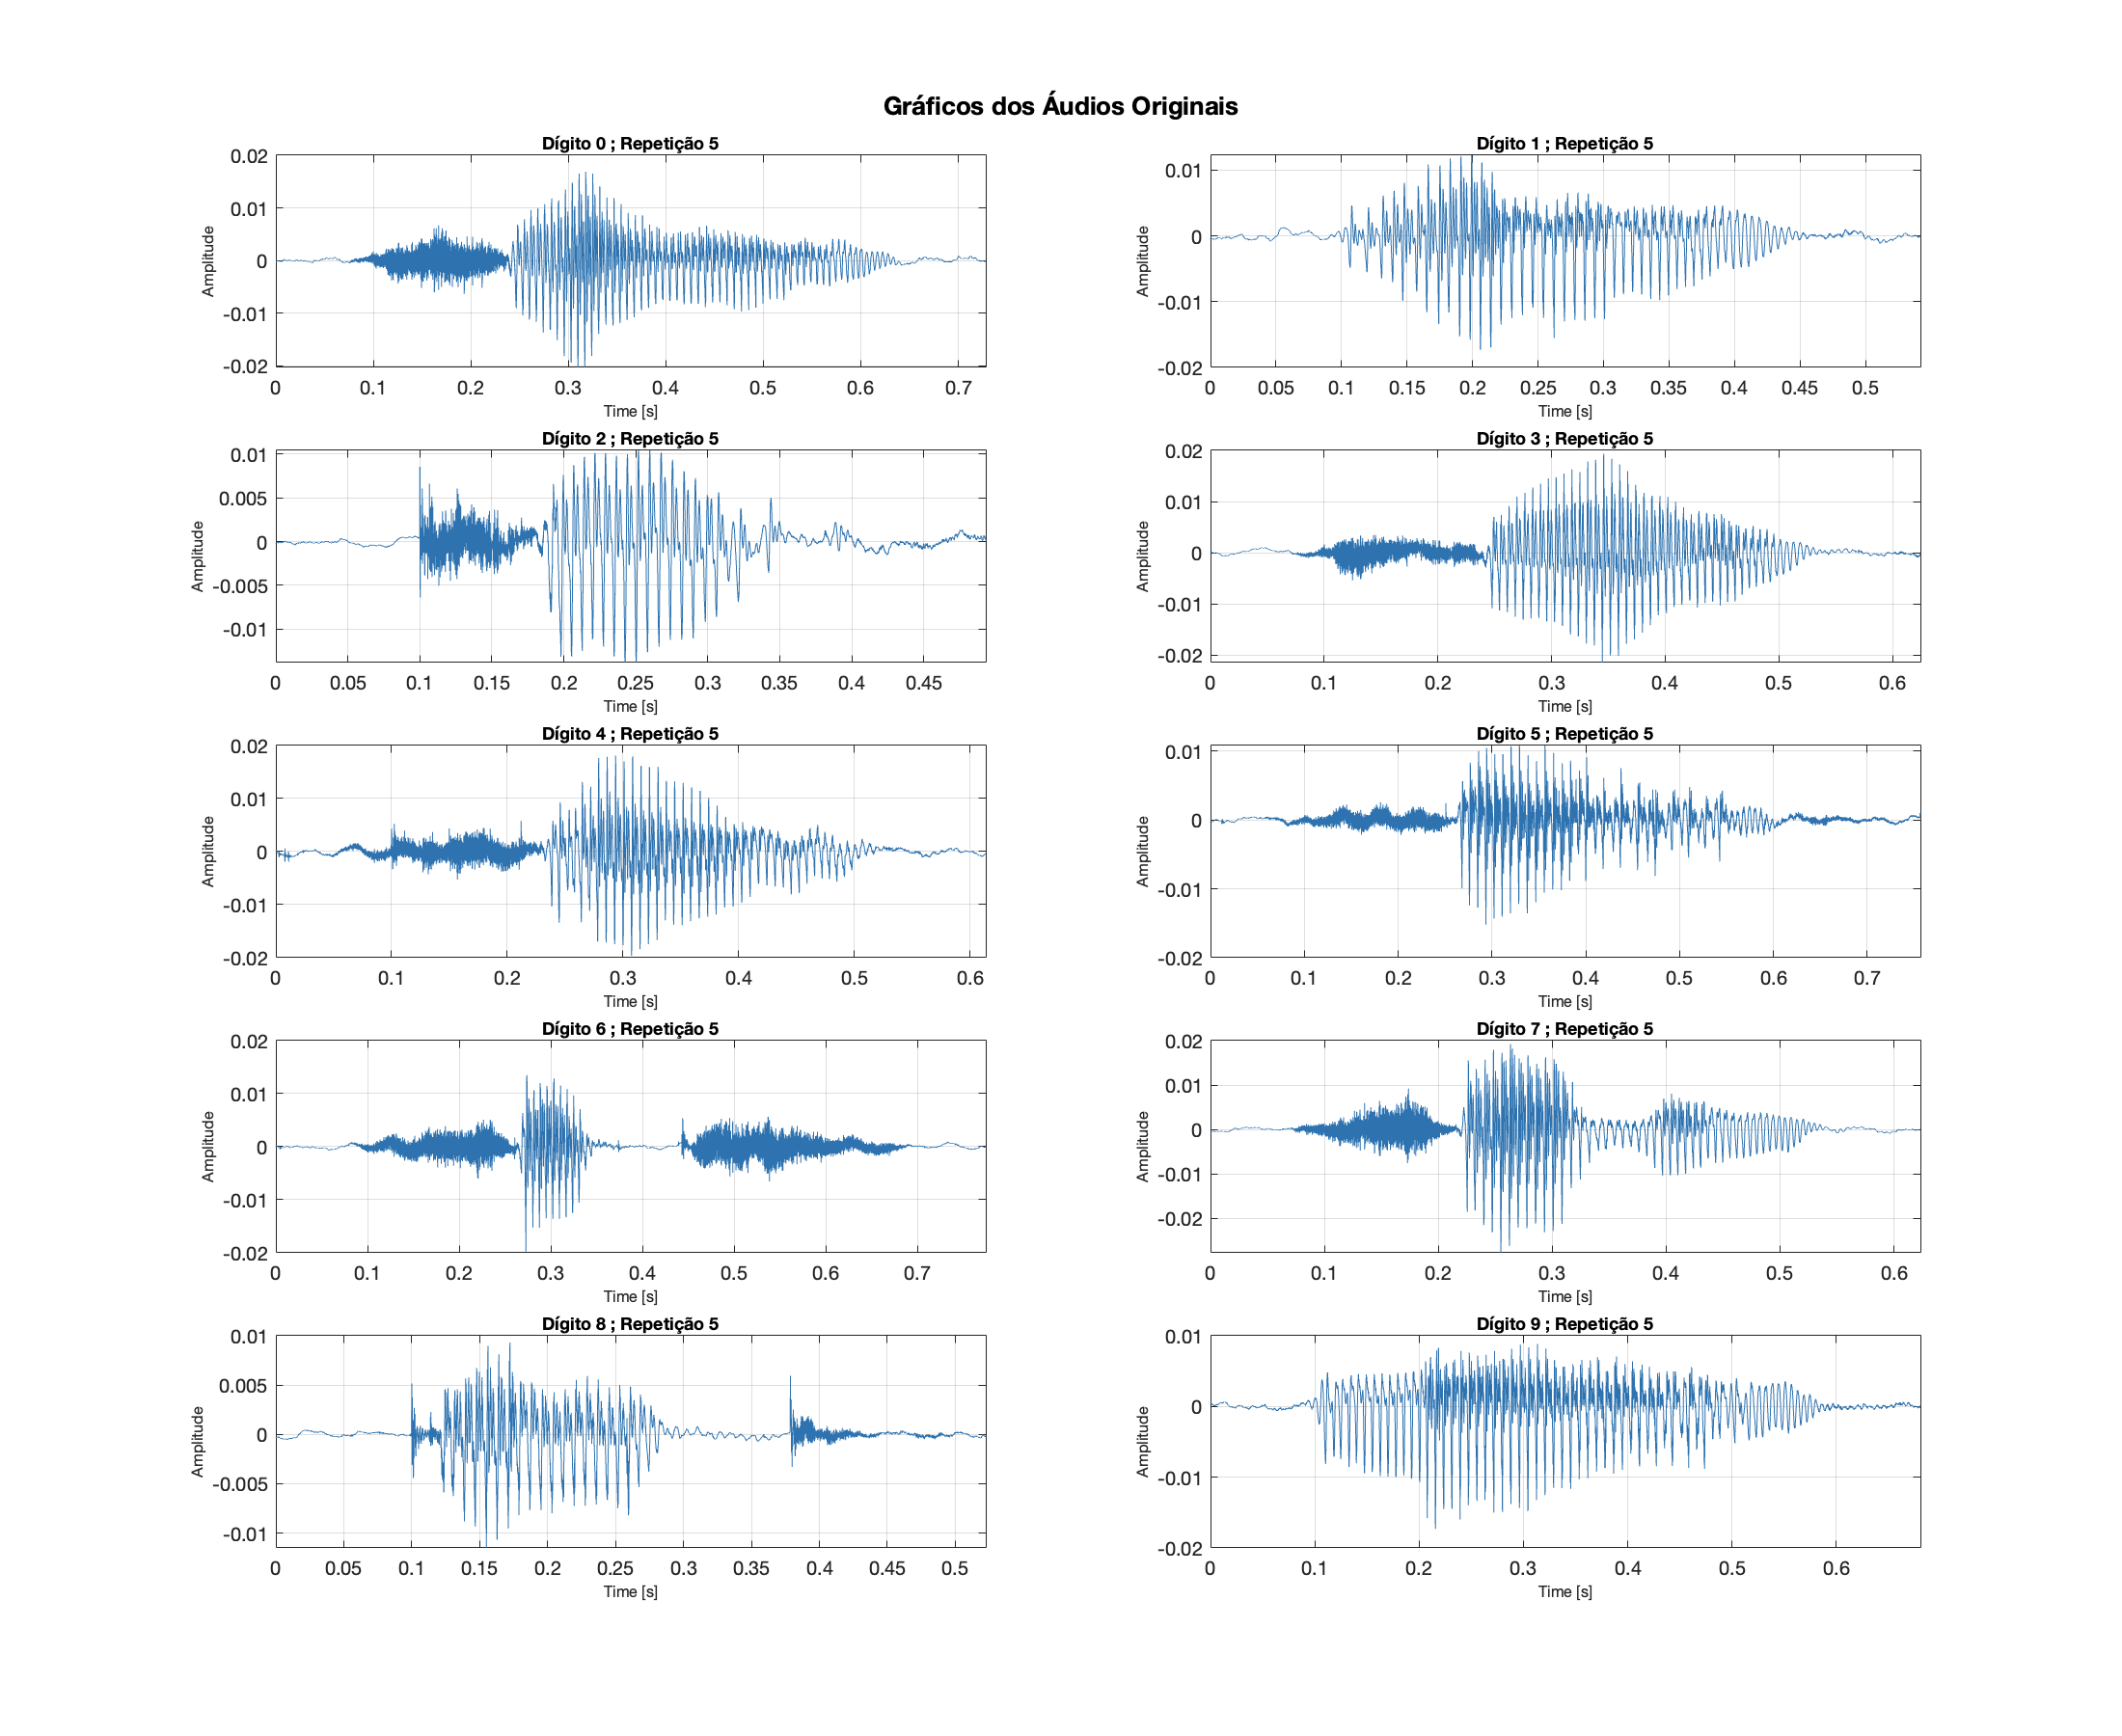


%% ================================================================
%  PONTO 3 – Representação Gráfica dos Sinais Originais
%  Exemplo: repetição 5
% ================================================================

REP_EXAMPLE = 5;

% Filtrar apenas a repetição escolhida e ordenar por dígito
mask   = (T.Repetition == REP_EXAMPLE);
subset = sortrows(T(mask,:), 'Digit');

figure('Name','Gráficos dos Áudios Originais', ...
       'NumberTitle','off', 'Position',[50 50 1100 900]);
sgtitle('Gráficos dos Áudios Originais', 'FontSize',13, 'FontWeight','bold');

for i = 1:height(subset)
    sig = subset.Signal{i};
    fs  = subset.SampleRate(i);
    t   = (0:numel(sig)-1) / fs;

    subplot(5, 2, i);
    plot(t, sig, 'Color',[0.18 0.45 0.69], 'LineWidth',0.5);
    title(sprintf('Dígito %d ; Repetição %d', subset.Digit(i), REP_EXAMPLE), ...
          'FontSize',9, 'FontWeight','bold');
    xlabel('Time [s]', 'FontSize',8);
    ylabel('Amplitude', 'FontSize',8);
    xlim([0, t(end)]); grid on;
end


%% ================================================================
%  PONTO 4 – Pré-processamento dos Sinais
%   a) Remover silêncio inicial via energia por janelas
%   b) Normalizar amplitude para [-1, 1]
%   c) Uniformizar duração (padding/trimming)
% ================================================================

% O sinal é dividido em janelas de WINDOW_MS ms. Para cada janela calcula-se
% a energia. Se a energia estiver abaixo de ENERGY_THRESH, considera-se silêncio.
WINDOW_MS     = 1;       % tamanho de janela (ms)
ENERGY_THRESH = 0.008;   % limiar (fracção da energia máxima)

% Calcular duração alvo: percentil 95 das durações após remover silêncio
trimmed_lens = zeros(N_files, 1);
for i = 1:N_files
    s = remove_silence(T.Signal{i}, T.SampleRate(i), WINDOW_MS, ENERGY_THRESH);
    trimmed_lens(i) = numel(s);
end
target_s   = prctile(trimmed_lens ./ T.SampleRate, 95);
target_len = round(target_s * T.SampleRate(1));
fprintf('Duração alvo (percentil 95): %.4f s  (%d amostras)\n', target_s, target_len);

Duração alvo (percentil 95): 0.6614 s  (31745 amostras)


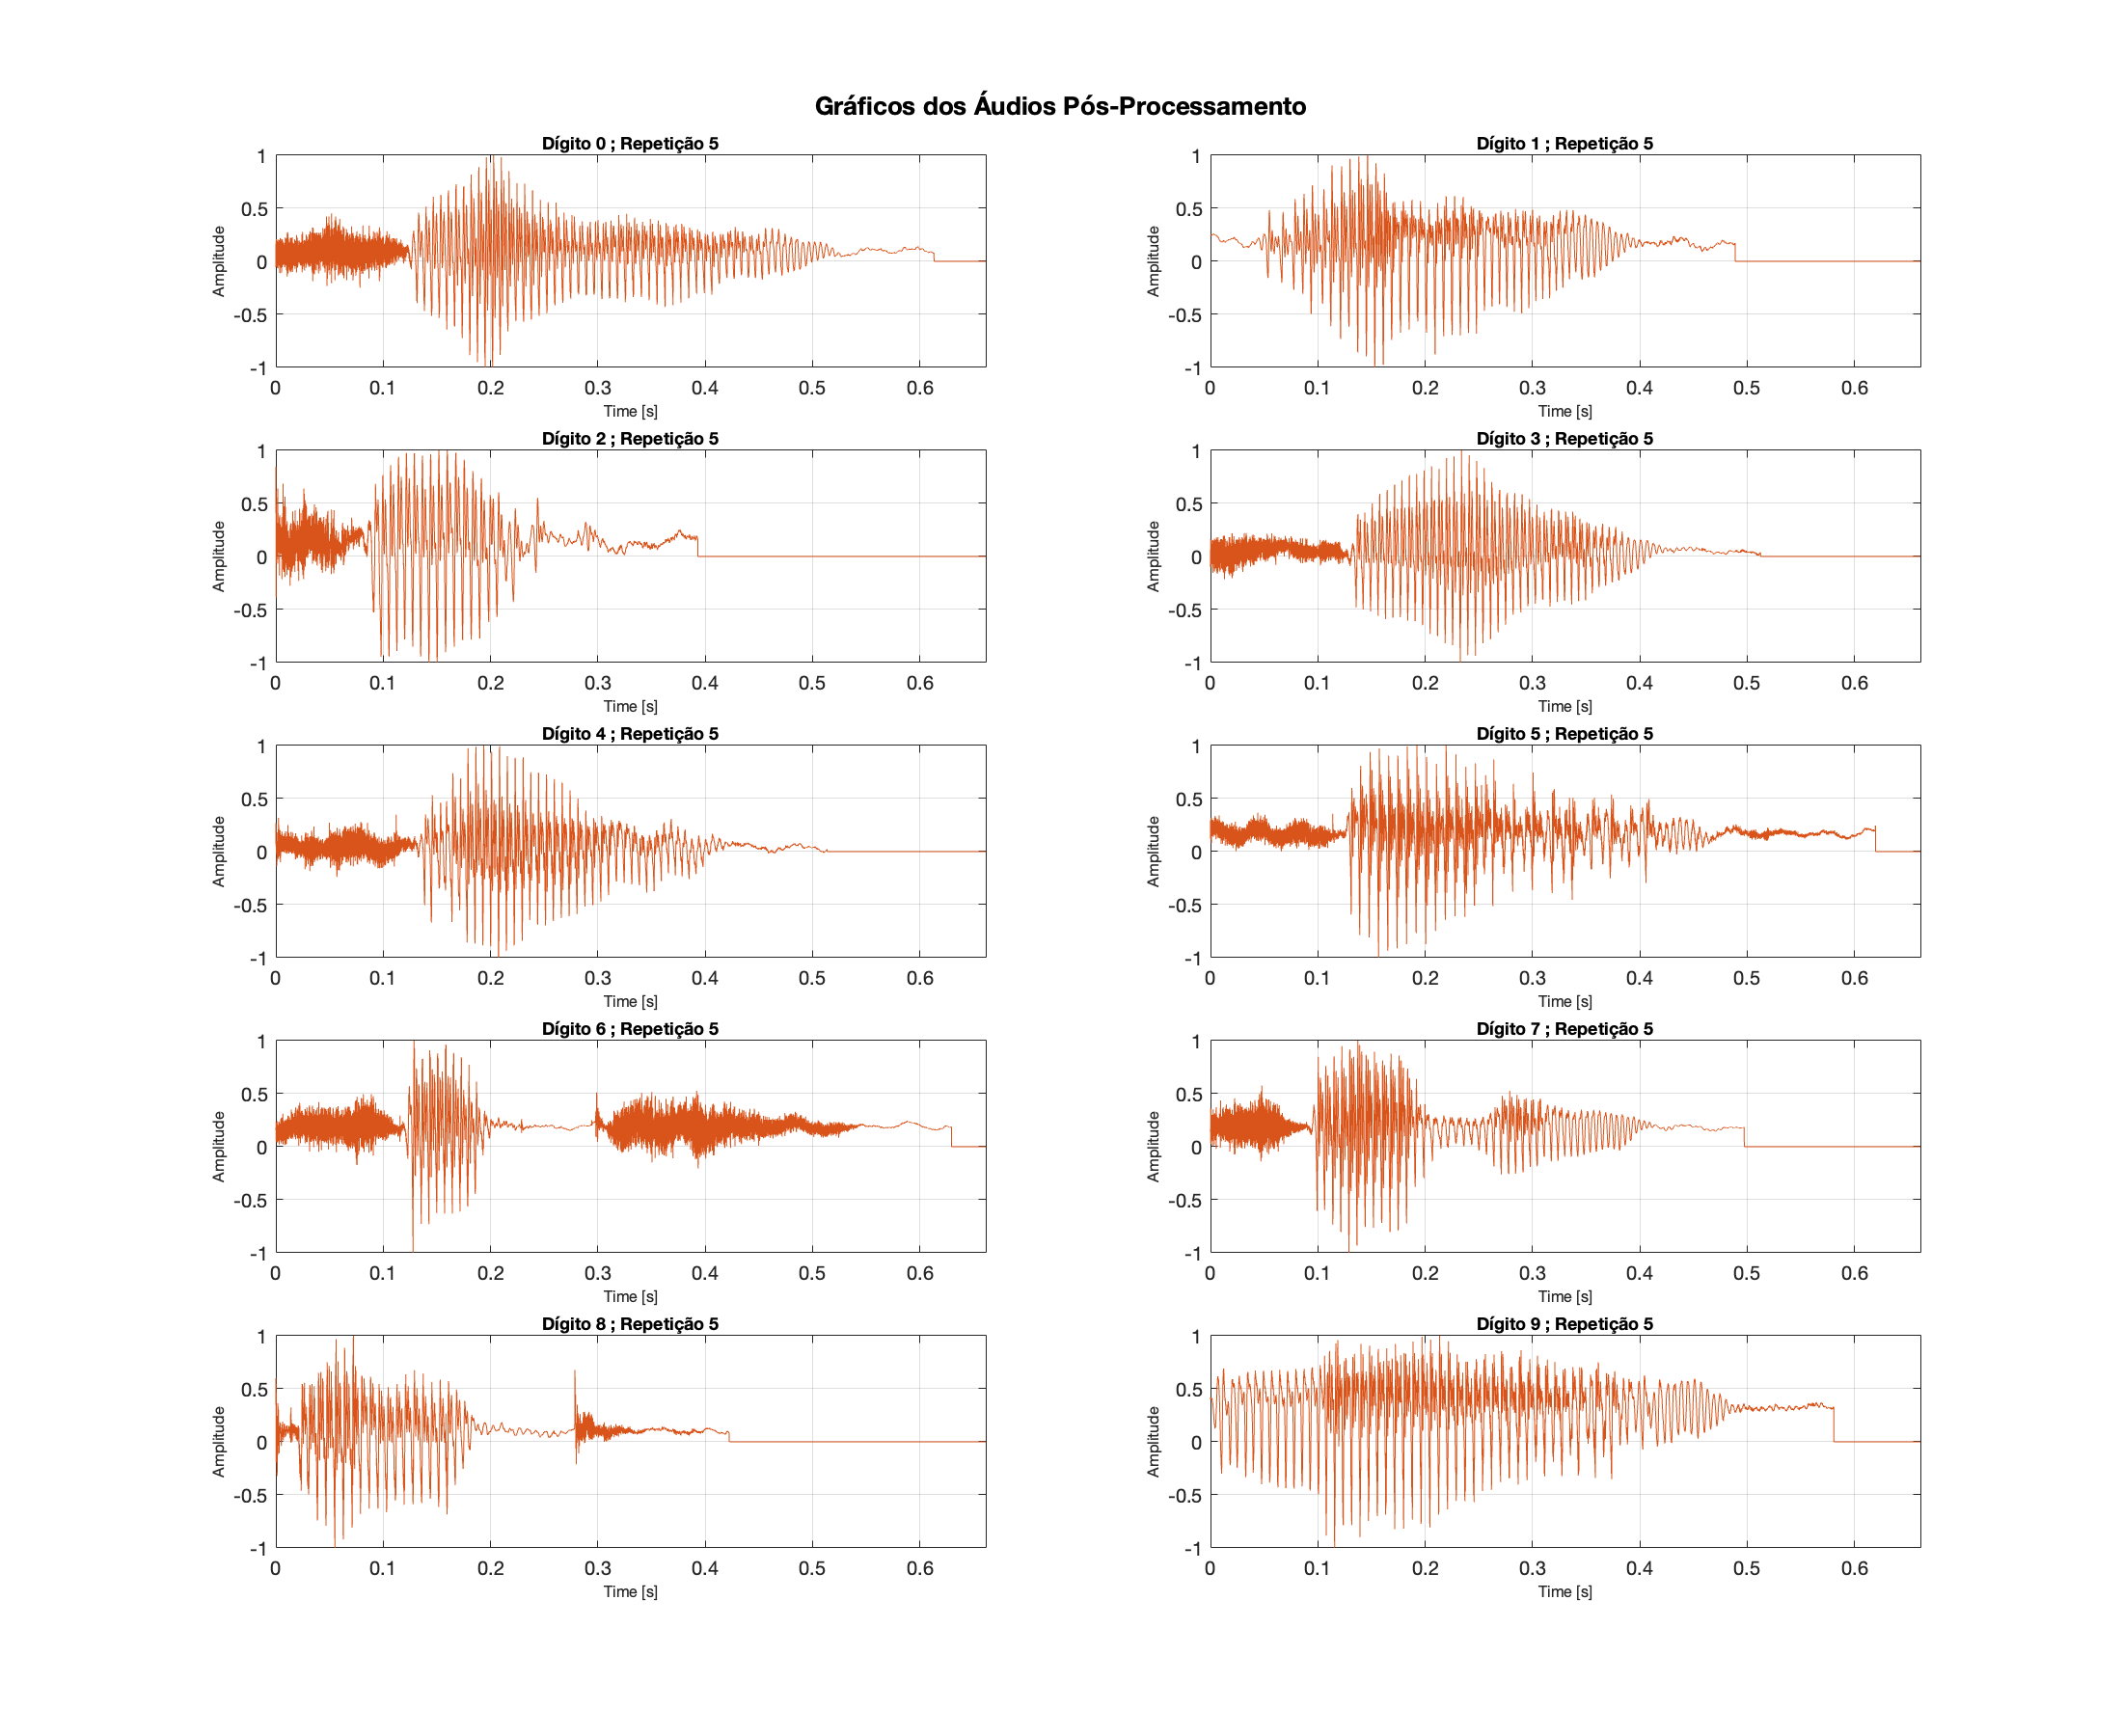


preprocessed = cell(N_files, 1);
for i = 1:N_files
    sig = remove_silence(T.Signal{i}, T.SampleRate(i), WINDOW_MS, ENERGY_THRESH);
    sig = norm_amplitude(sig);
    sig = pad_trim(sig, target_len);
    preprocessed{i} = sig;
end

T.SignalPreprocessed = preprocessed;

%% ================================================================
%  PONTO 5 – Gráficos dos Sinais Pré-processados
%  (repetição 5 — igual ao ponto 3)
% ================================================================

mask_pre   = (T.Repetition == REP_EXAMPLE);
subset_pre = sortrows(T(mask_pre,:), 'Digit');

figure('Name','Gráficos dos Áudios Pós-Processamento', ...
       'NumberTitle','off', 'Position',[50 50 1100 900]);
sgtitle('Gráficos dos Áudios Pós-Processamento', 'FontSize',13, 'FontWeight','bold');

for i = 1:height(subset_pre)
    sig = subset_pre.SignalPreprocessed{i};
    fs  = subset_pre.SampleRate(i);
    t   = (0:numel(sig)-1) / fs;

    subplot(5, 2, i);
    plot(t, sig, 'Color',[0.85 0.33 0.10], 'LineWidth',0.5);
    title(sprintf('Dígito %d ; Repetição %d', subset_pre.Digit(i), REP_EXAMPLE), ...
          'FontSize',9, 'FontWeight','bold');
    xlabel('Time [s]', 'FontSize',8);
    ylabel('Amplitude', 'FontSize',8);
    xlim([0, t(end)]); grid on;
end

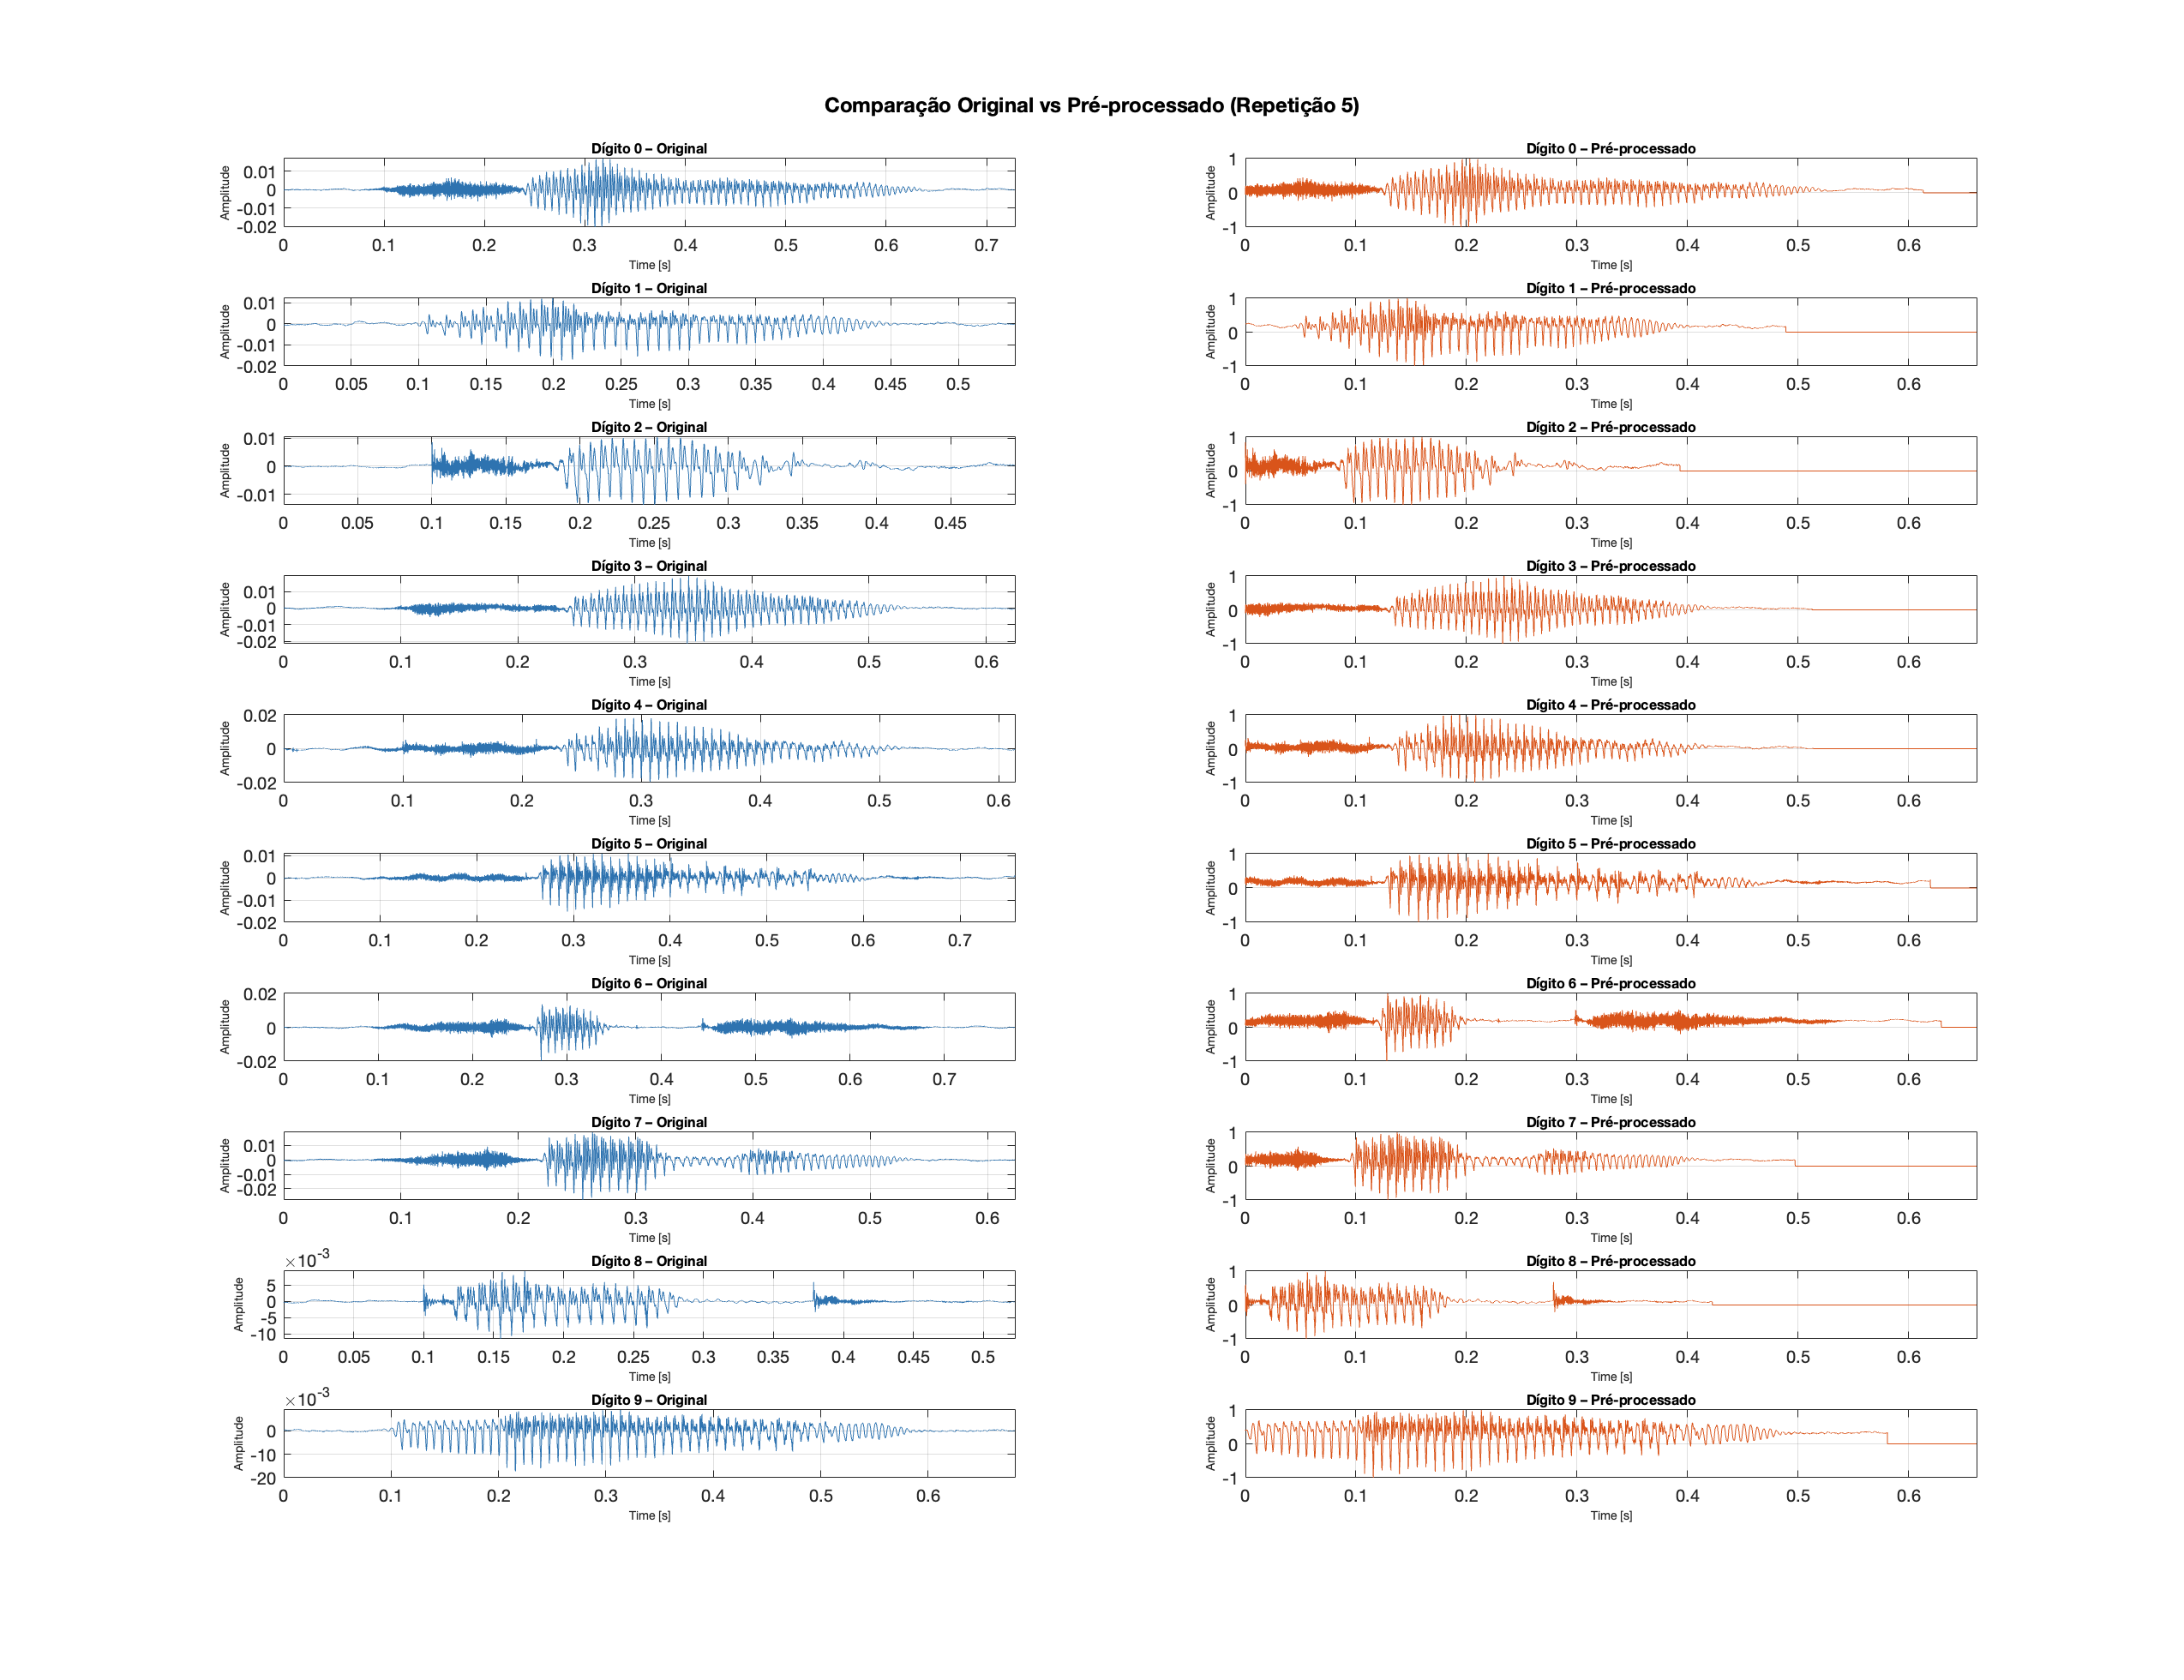




%% ================================================================
%  PONTO 6 – Comparação Visual: Original vs Pré-processado
%  Grelha com os 10 dígitos lado a lado
% ================================================================

digits_list = sort(unique(T.Digit))';

figure('Name','Comparação Original vs Pré-processado', ...
       'NumberTitle','off', 'Position',[50 50 1300 1000]);
sgtitle('Comparação Original vs Pré-processado (Repetição 5)', ...
        'FontSize',12, 'FontWeight','bold');

for i = 1:numel(digits_list)
    d   = digits_list(i);
    idx = find(T.Digit==d & T.Repetition==REP_EXAMPLE, 1);

    fs    = T.SampleRate(idx);
    s_ori = T.Signal{idx};
    s_pre = T.SignalPreprocessed{idx};
    t_ori = (0:numel(s_ori)-1) / fs;
    t_pre = (0:numel(s_pre)-1) / fs;

    subplot(10, 2, 2*i-1);
    plot(t_ori, s_ori, 'Color',[0.18 0.45 0.69], 'LineWidth',0.5);
    title(sprintf('Dígito %d – Original', d), 'FontSize',8, 'FontWeight','bold');
    xlabel('Time [s]','FontSize',7); ylabel('Amplitude','FontSize',7);
    xlim([0, t_ori(end)]); grid on;

    subplot(10, 2, 2*i);
    plot(t_pre, s_pre, 'Color',[0.85 0.33 0.10], 'LineWidth',0.5);
    title(sprintf('Dígito %d – Pré-processado', d), 'FontSize',8, 'FontWeight','bold');
    xlabel('Time [s]','FontSize',7); ylabel('Amplitude','FontSize',7);
    xlim([0, t_pre(end)]); grid on;
end


fprintf(['Observações:\n' ...
    '- Silêncio inicial removido: todos os sinais começam no onset da fala.\n' ...
    '- Amplitude normalizada em [-1, 1]: elimina variações de ganho.\n' ...
    '- Duração uniforme: %d amostras (%.3f s) para todos os sinais.\n\n'], ...
    target_len, target_len / T.SampleRate(1));

Observações:
- Silêncio inicial removido: todos os sinais começam no onset da fala.
- Amplitude normalizada em [-1, 1]: elimina variações de ganho.
- Duração uniforme: 31745 amostras (0.661 s) para todos os sinais.




%% ================================================================
%  PONTO 7 – Características Temporais (5 features por áudio)
%
%  T1 – Energia total
%  T2 – Desvio padrão da amplitude
%  T3 – Zero-Crossing Rate (ZCR)
%  T4 – Energia no onset (primeiros 25%)
%  T5 – Duração da fala (do onset ao último frame activo)
% ================================================================
fprintf('=== PONTO 7: Cálculo de features temporais ===\n');

=== PONTO 7: Cálculo de features temporais ===



feat_energy_total = zeros(N_files, 1);
feat_amp_std      = zeros(N_files, 1);
feat_zcr          = zeros(N_files, 1);
feat_energy_onset = zeros(N_files, 1);
feat_duration     = zeros(N_files, 1);

for i = 1:N_files
    sig  = T.SignalPreprocessed{i};
    n    = numel(sig);
    q1   = floor(n / 4);
    fs   = T.SampleRate(i);

    feat_energy_total(i) = sum(sig .^ 2);
    feat_amp_std(i)      = std(sig);
    feat_zcr(i)          = sum(abs(diff(sign(sig)))) / (2 * n);
    feat_energy_onset(i) = sum(sig(1:q1) .^ 2);   % energia nos primeiros 25% do sinal

    % Duração: do primeiro ao último frame com energia acima do limiar
    % Usa as mesmas janelas do pré-processamento (WINDOW_MS, ENERGY_THRESH)
    feat_duration(i) = compute_duration(sig, fs, WINDOW_MS, ENERGY_THRESH);
end

T.FeatEnergyTotal = feat_energy_total;
T.FeatAmpStd      = feat_amp_std;
T.FeatZCR         = feat_zcr;
T.FeatEnergyOnset = feat_energy_onset;
T.FeatDuration    = feat_duration;
fprintf('  Colunas adicionadas à tabela.\n\n');

  Colunas adicionadas à tabela.




% Duração média por dígito
fprintf('  Duração média por dígito:\n');

  Duração média por dígito:


for d = 0:9
    idx_d = T.Digit == d;
    fprintf('    Dígito %d: %.3f s\n', d, mean(T.FeatDuration(idx_d)));
end

    Dígito 0: 0.523 s
    Dígito 1: 0.405 s
    Dígito 2: 0.422 s
    Dígito 3: 0.498 s
    Dígito 4: 0.442 s
    Dígito 5: 0.457 s
    Dígito 6: 0.572 s
    Dígito 7: 0.516 s
    Dígito 8: 0.476 s
    Dígito 9: 0.557 s


fprintf('\n');

%% ================================================================
%  PONTO 8 – Seleção Gráfica das Características Temporais
% ================================================================
fprintf('=== PONTO 8: Seleção de Features Temporais ===\n');

=== PONTO 8: Seleção de Features Temporais ===


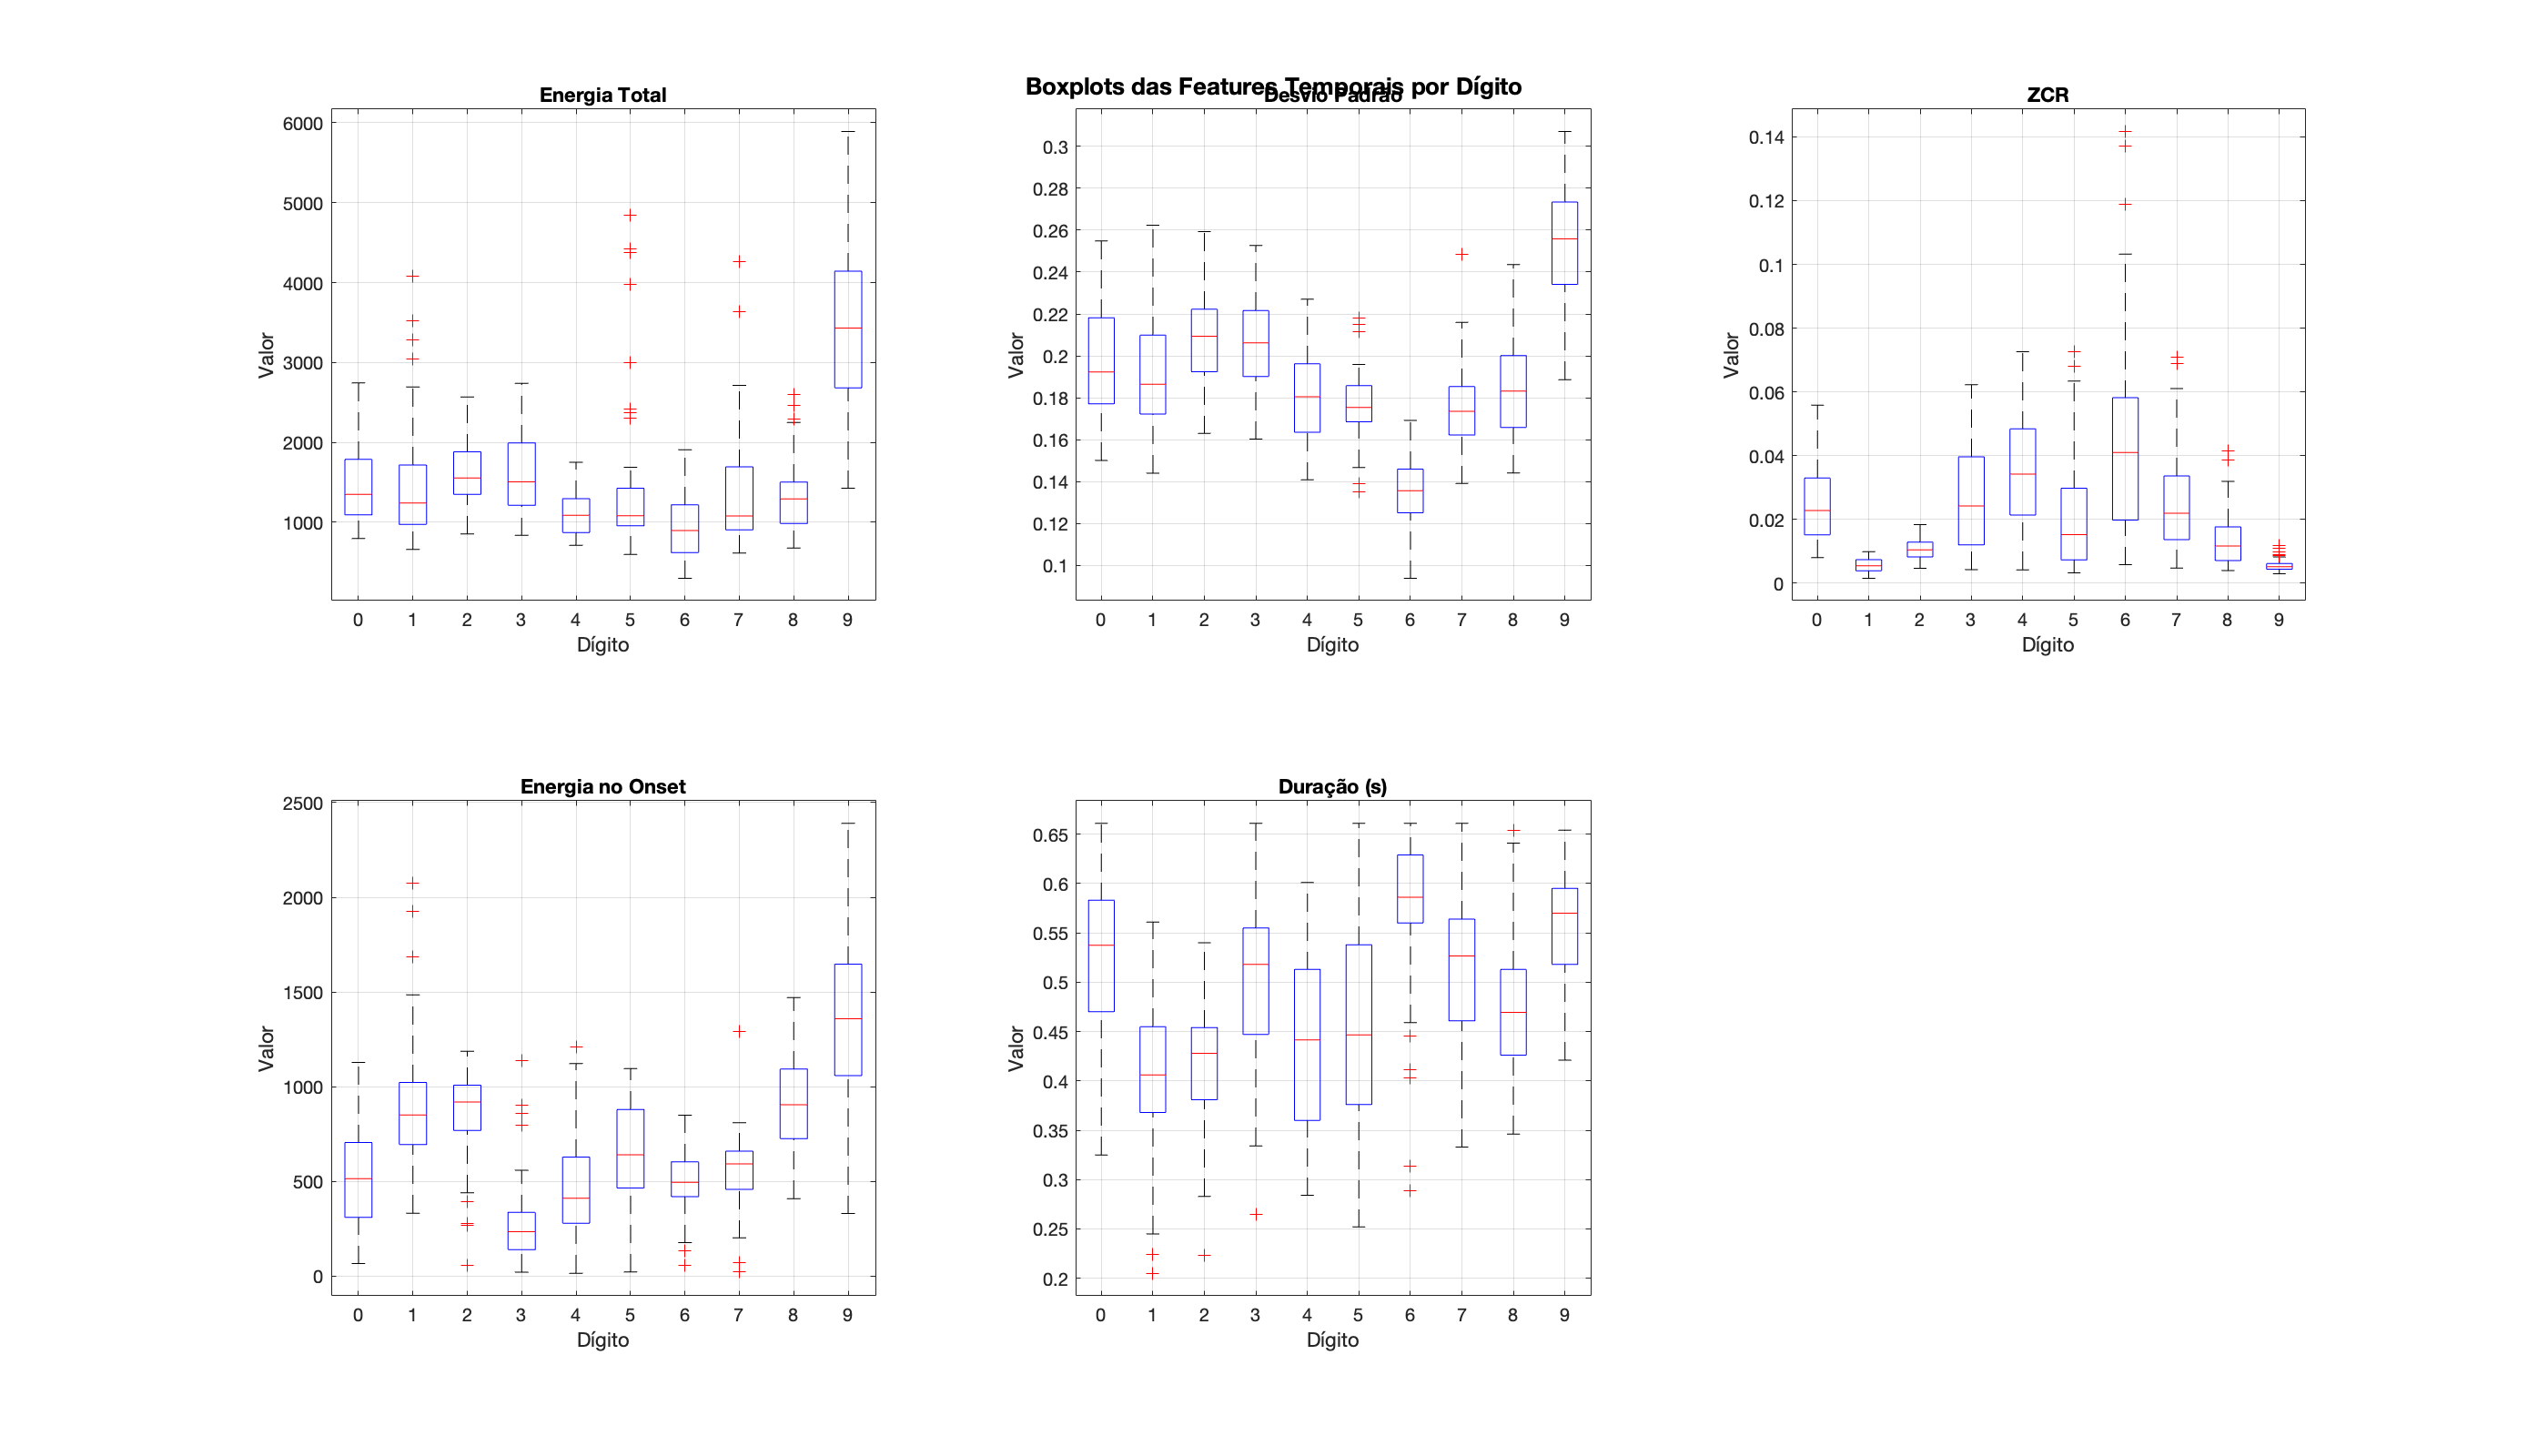


% Boxplots das 5 features para todos os dígitos
figure('Name','Boxplots - Todas as Features Temporais', ...
       'NumberTitle','off', 'Position',[50 50 1400 800]);
sgtitle('Boxplots das Features Temporais por Dígito', 'FontSize',13, 'FontWeight','bold');

subplot(2,3,1); boxplot(T.FeatEnergyTotal, T.Digit); title('Energia Total');     xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(2,3,2); boxplot(T.FeatAmpStd,      T.Digit); title('Desvio Padrão');     xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(2,3,3); boxplot(T.FeatZCR,         T.Digit); title('ZCR');               xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(2,3,4); boxplot(T.FeatEnergyOnset, T.Digit); title('Energia no Onset'); xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(2,3,5); boxplot(T.FeatDuration,    T.Digit); title('Duração (s)');       xlabel('Dígito'); ylabel('Valor'); grid on;

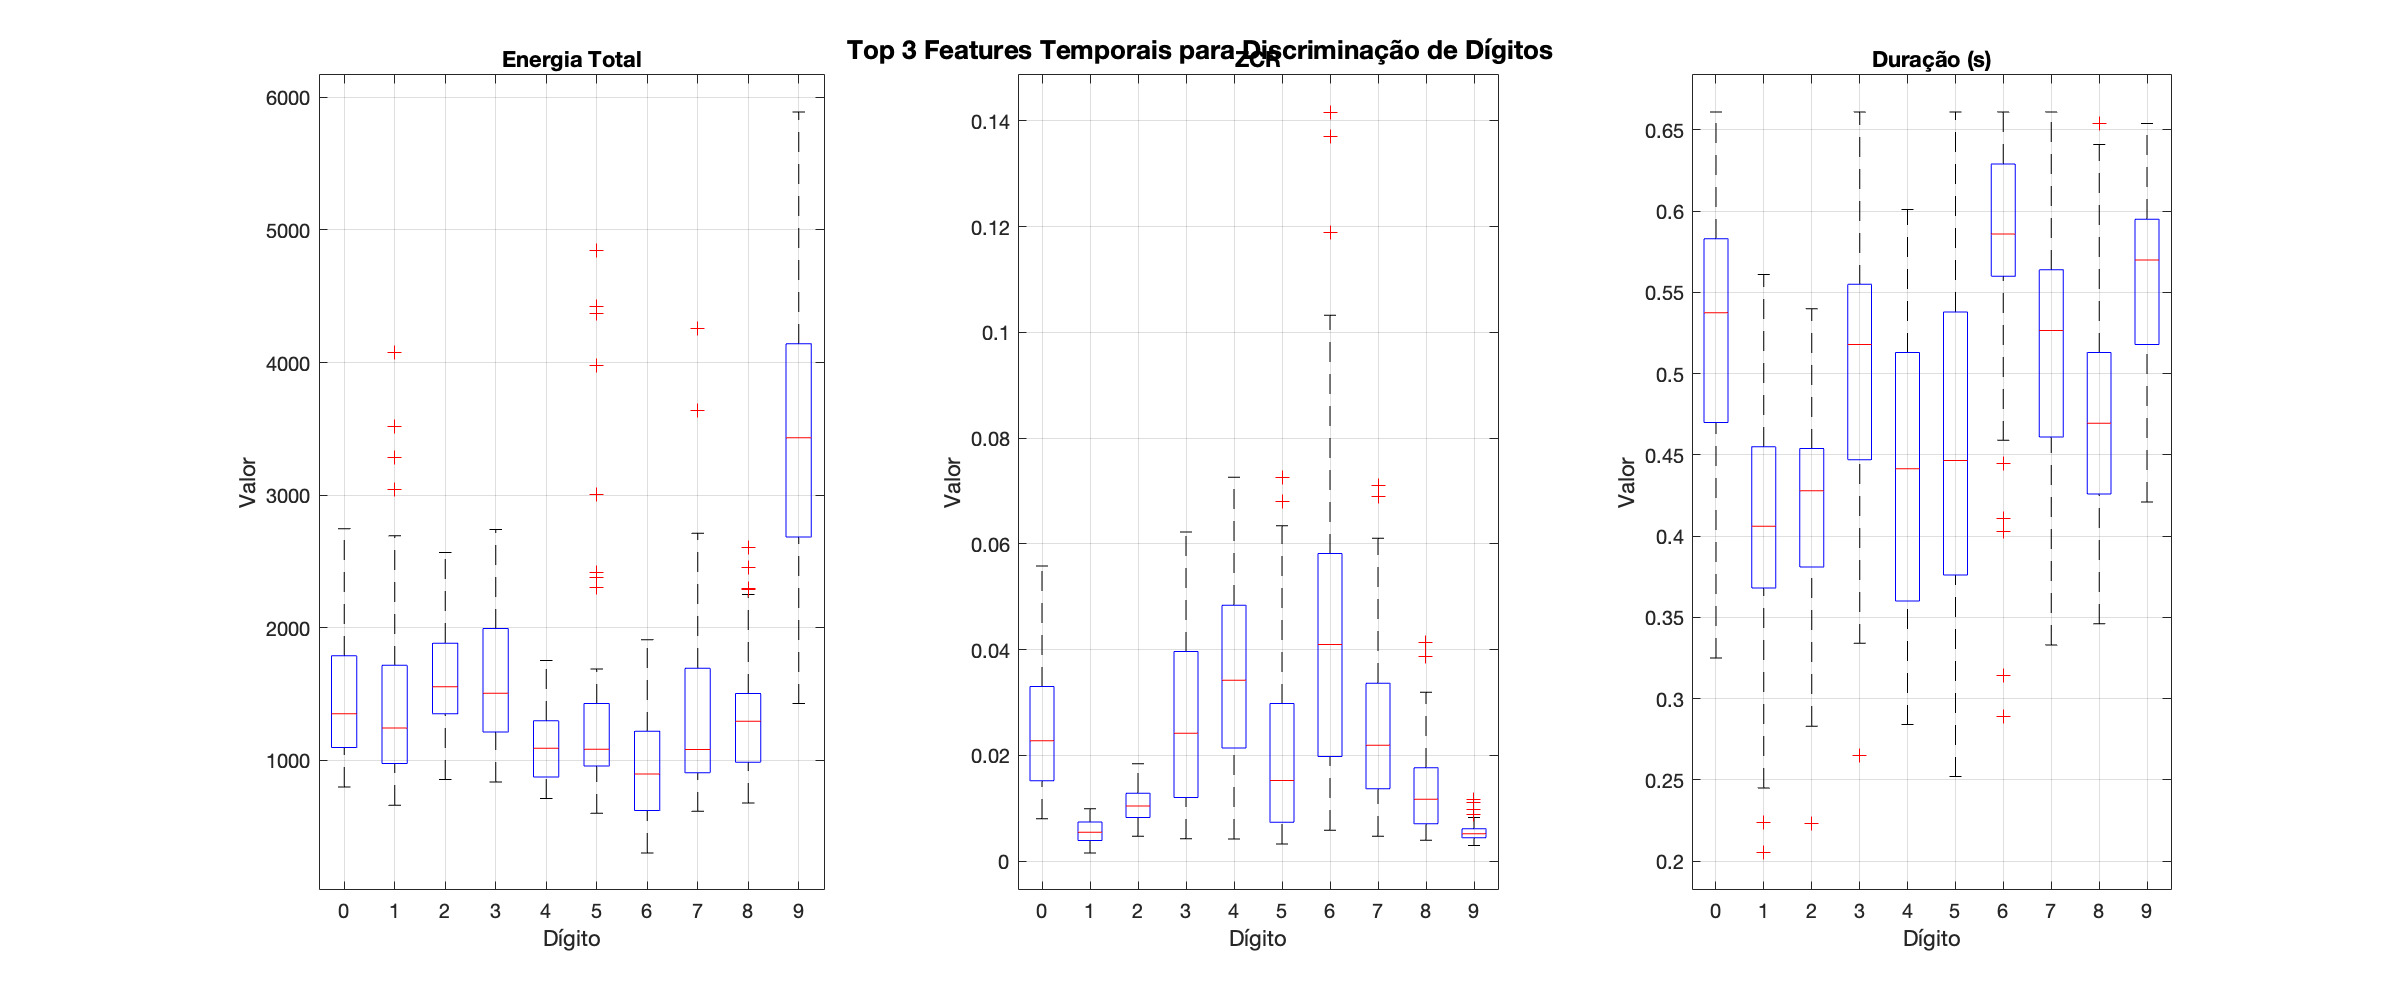


% As 3 melhores features num gráfico separado
figure('Name','Boxplots - Top 3 Features Temporais', ...
       'NumberTitle','off', 'Position',[50 50 1200 500]);
sgtitle('Top 3 Features Temporais para Discriminação de Dígitos', 'FontSize',13, 'FontWeight','bold');

subplot(1,3,1); boxplot(T.FeatEnergyTotal, T.Digit); title('Energia Total');  xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(1,3,2); boxplot(T.FeatZCR,         T.Digit); title('ZCR');            xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(1,3,3); boxplot(T.FeatDuration,    T.Digit); title('Duração (s)');    xlabel('Dígito'); ylabel('Valor'); grid on;


fprintf('  Features seleccionadas (top 3):\n');

  Features seleccionadas (top 3):


fprintf('  1. ZCR         – "six" tem ZCR muito alto (fricativa "s"); "one" e "nine" muito baixo.\n');

  1. ZCR         – "six" tem ZCR muito alto (fricativa "s"); "one" e "nine" muito baixo.


fprintf('  2. Energia Total – "six" tem energia claramente mais baixa; "nine" e "zero" mais alta.\n');

  2. Energia Total – "six" tem energia claramente mais baixa; "nine" e "zero" mais alta.


fprintf('  3. Duracao       – "one" e o mais curto; "nine", "zero" e "six" os mais longos.\n\n');

  3. Duracao       – "one" e o mais curto; "nine", "zero" e "six" os mais longos.




%% ================================================================
%  PONTO 9 – Série Complexa de Fourier (Espectro)
% ================================================================
fprintf('=== PONTO 9: Coeficientes da Série Complexa de Fourier ===\n');

=== PONTO 9: Coeficientes da Série Complexa de Fourier ===



fft_coeffs = cell(N_files, 1);
for i = 1:N_files
    sig          = T.SignalPreprocessed{i};
    N            = numel(sig);
    fft_coeffs{i} = fft(sig) / N;   % c[k] = X[k]/N — coeficientes da série complexa de Fourier
end
T.FFT_Coeffs = fft_coeffs;
fprintf('  Coeficientes guardados na tabela.\n\n');

  Coeficientes guardados na tabela.




%% ================================================================
%  PONTO 10 – Espectro de Amplitude Mediano e Quartis
% ================================================================
fprintf('=== PONTO 10: Espectro de Amplitude Mediano e Quartis ===\n');

=== PONTO 10: Espectro de Amplitude Mediano e Quartis ===


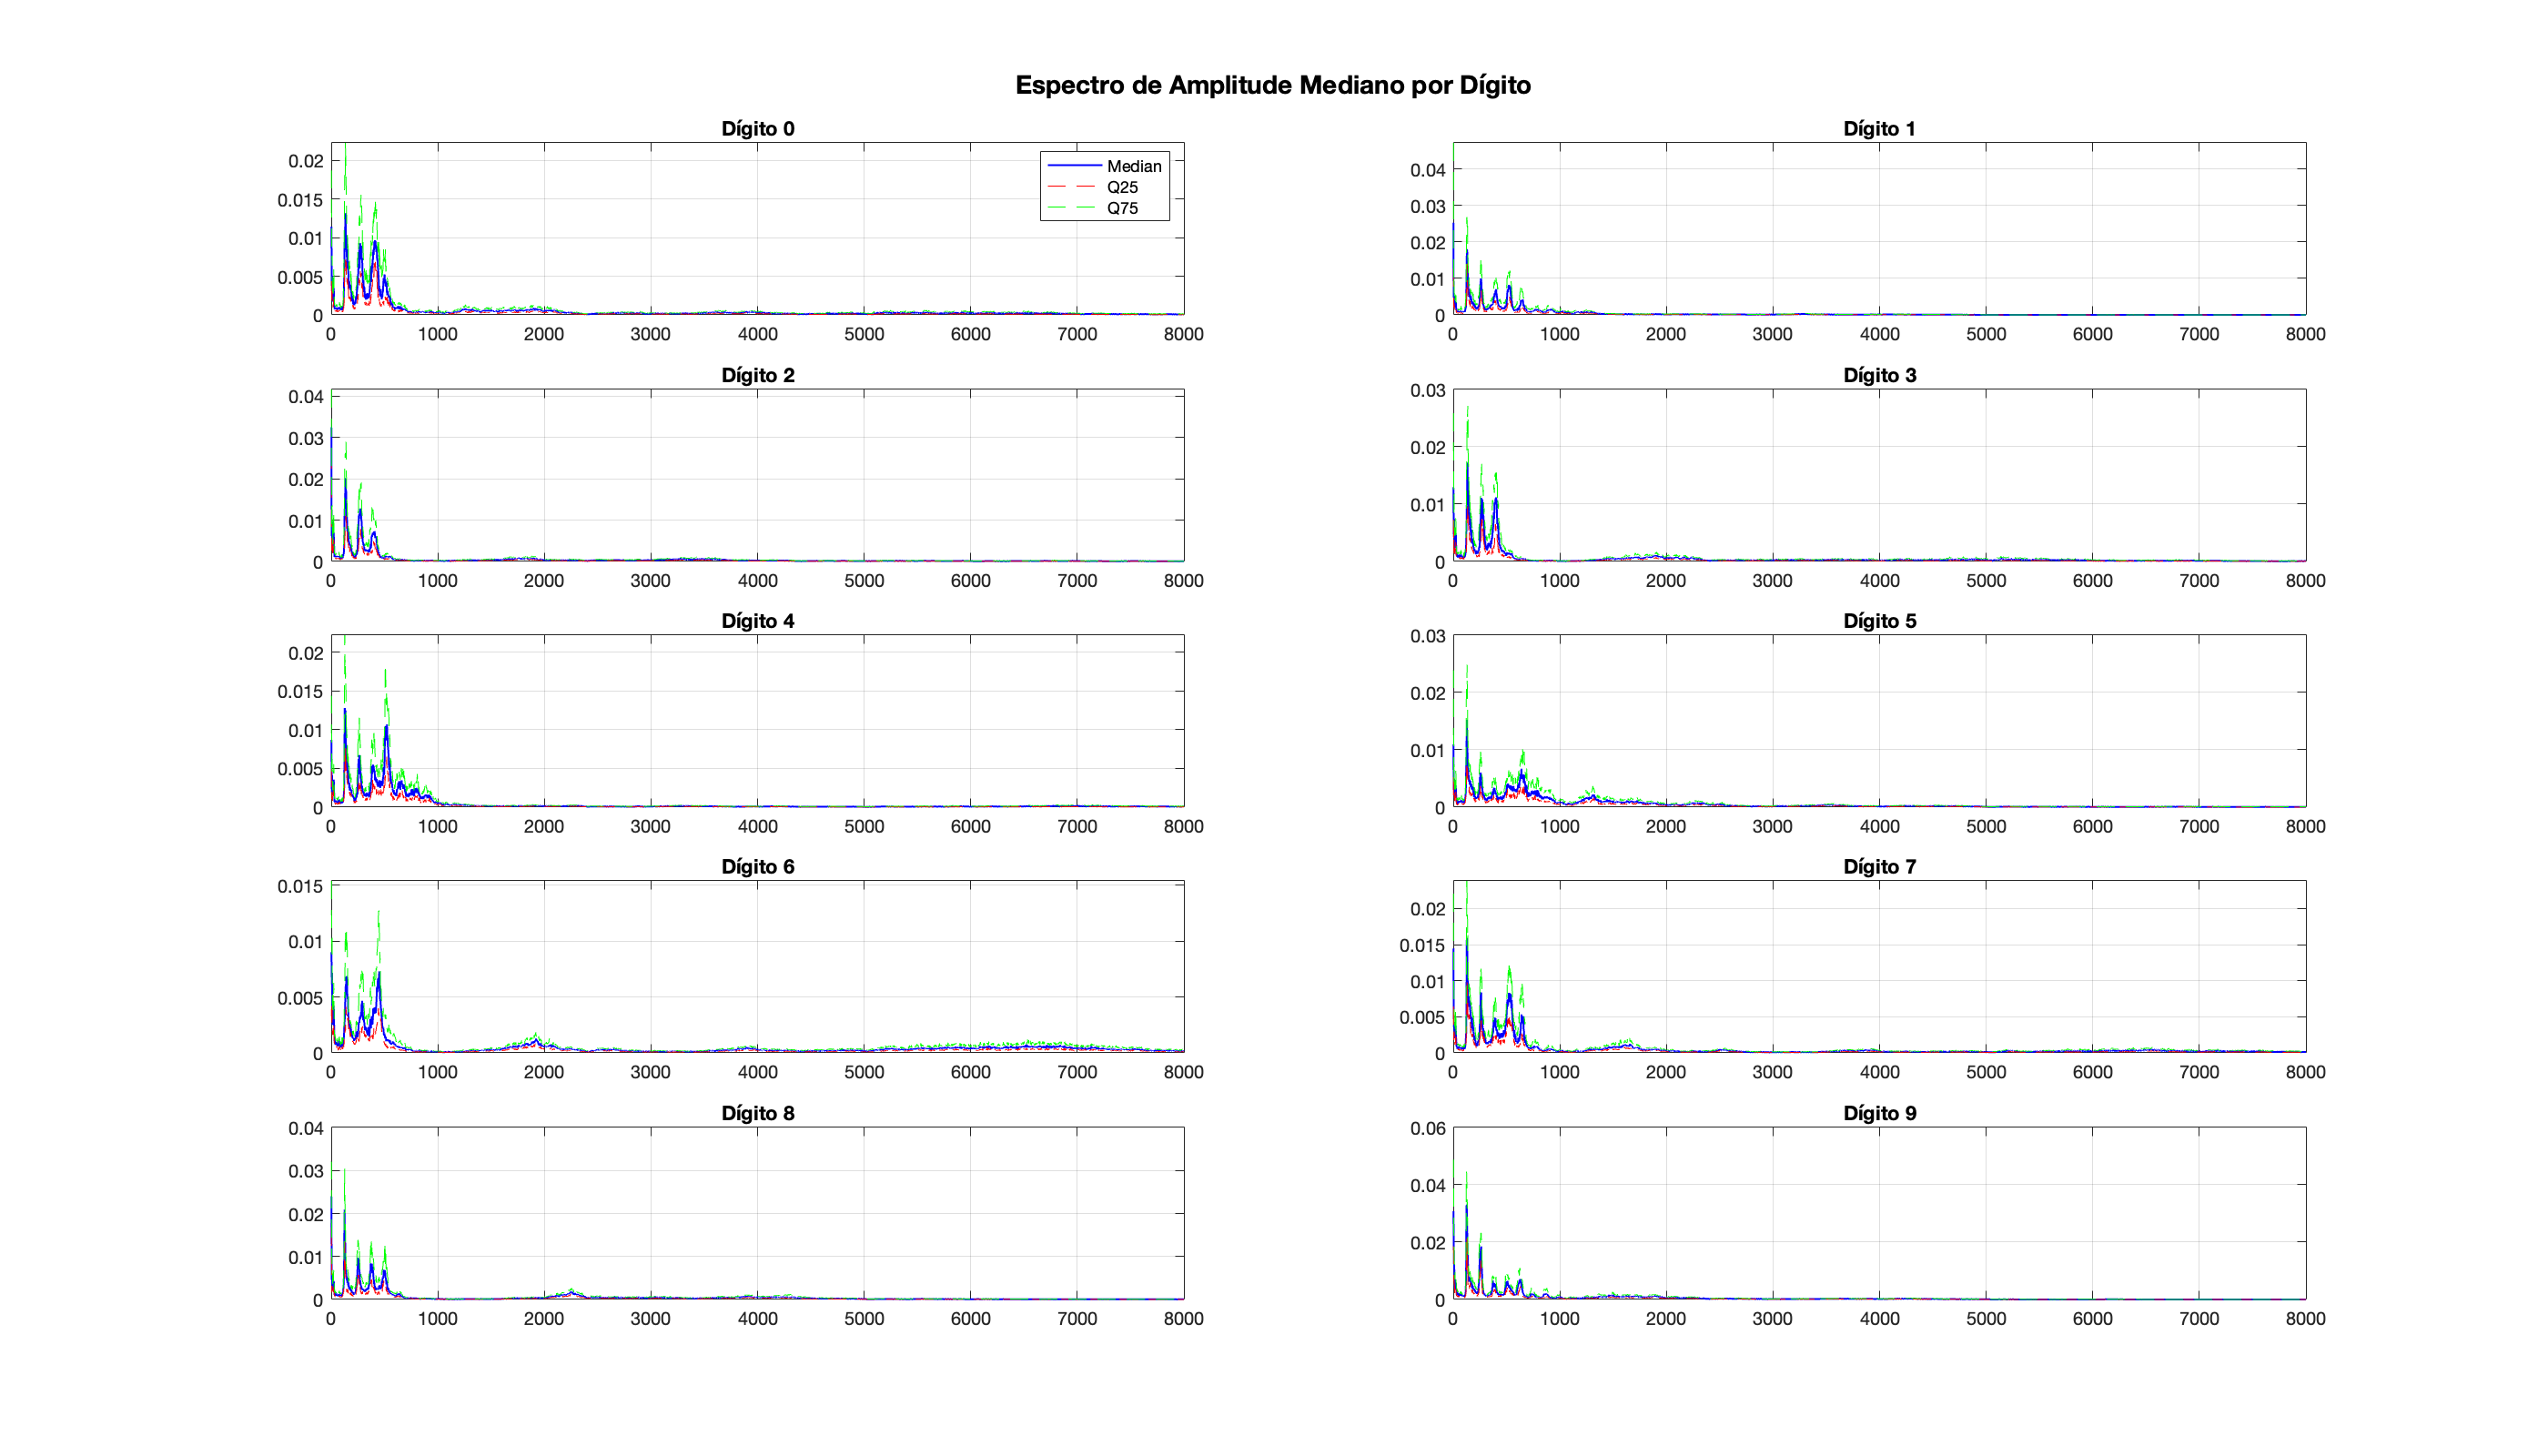


N_fft     = target_len;
% Ignorar o bin 0 Hz (componente DC = média do sinal).
% Após normalização, todos os sinais têm média ~0, logo o DC é inútil para discriminação.
% pos_freqs começa em 2 (bin 1 = 0 Hz é excluído).
pos_freqs = 2:floor(N_fft/2);
fs_plot   = T.SampleRate(1);
freq_axis = (1:floor(N_fft/2)-1) * (fs_plot / N_fft);   % frequências em Hz, sem o 0 Hz

figure('Name','Espectro de Amplitude', 'Position',[50 50 1400 800]);
sgtitle('Espectro de Amplitude Mediano por Dígito', 'FontSize',14, 'FontWeight','bold');

for d = 0:9
    idx_d = find(T.Digit == d);
    num_d = length(idx_d);

    amp_matrix = zeros(num_d, length(pos_freqs));
    for k = 1:num_d
        % Os coeficientes já foram normalizados por N no ponto 9 (fft/N)
        % por isso apenas tomamos o módulo directamente
        amp_full = abs(T.FFT_Coeffs{idx_d(k)});
        amp_matrix(k, :) = amp_full(pos_freqs);
    end

    med_spec = quantile(amp_matrix, 0.50, 1);
    q25_spec = quantile(amp_matrix, 0.25, 1);
    q75_spec = quantile(amp_matrix, 0.75, 1);

    subplot(5, 2, d+1);
    plot(freq_axis, med_spec, 'b', 'LineWidth',1); hold on;
    plot(freq_axis, q25_spec, 'r--', 'LineWidth',0.5);
    plot(freq_axis, q75_spec, 'g--', 'LineWidth',0.5);
    title(sprintf('Dígito %d', d));
    xlim([0, 8000]);   % visualização focada até 8 kHz
    if d == 0, legend('Median','Q25','Q75'); end
    grid on;
end


%% ================================================================
%  PONTO 11 – Características Espectrais (5 features)
%
%  S1 – Centróide espectral
%  S2 – Máximo espectral (amplitude)
%  S3 – Máximo espectral (frequência)
%  S4 – Média da amplitude espectral nas frequências positivas
%  S5 – Spectral edge frequency (85%)
% ================================================================
fprintf('=== PONTO 11: Cálculo de Features Espectrais ===\n');

=== PONTO 11: Cálculo de Features Espectrais ===



feat_spec_centroid = zeros(N_files, 1);
feat_spec_max_amp  = zeros(N_files, 1);
feat_spec_max_freq = zeros(N_files, 1);
feat_spec_mean     = zeros(N_files, 1);
feat_spec_rolloff  = zeros(N_files, 1);

for i = 1:N_files
    amp = abs(T.FFT_Coeffs{i}(pos_freqs));

    % Centróide espectral: frequência média ponderada pela amplitude
    feat_spec_centroid(i) = sum(freq_axis' .* amp) / (sum(amp) + eps);

    % Frequência e amplitude do pico espectral
    [m_amp, m_idx]        = max(amp);
    feat_spec_max_amp(i)  = m_amp;
    feat_spec_max_freq(i) = freq_axis(m_idx);

    feat_spec_mean(i) = mean(amp);

    % Spectral edge frequency: frequência abaixo da qual está 85% da energia espectral
    cum_energy   = cumsum(amp .^ 2);
    total_energy = cum_energy(end);
    idx_rolloff  = find(cum_energy >= 0.85 * total_energy, 1);
    if isempty(idx_rolloff), idx_rolloff = length(freq_axis); end
    feat_spec_rolloff(i) = freq_axis(idx_rolloff);
end

T.FeatSpecCentroid = feat_spec_centroid;
T.FeatSpecMaxAmp   = feat_spec_max_amp;
T.FeatSpecMaxFreq  = feat_spec_max_freq;
T.FeatSpecMean     = feat_spec_mean;
T.FeatSpecRolloff  = feat_spec_rolloff;
fprintf('  Features espectrais calculadas e guardadas na tabela.\n\n');

  Features espectrais calculadas e guardadas na tabela.




%% ================================================================
%  PONTO 12 – Seleção Gráfica das Características Espectrais
% ================================================================
fprintf('=== PONTO 12: Seleção de Features Espectrais ===\n');

=== PONTO 12: Seleção de Features Espectrais ===


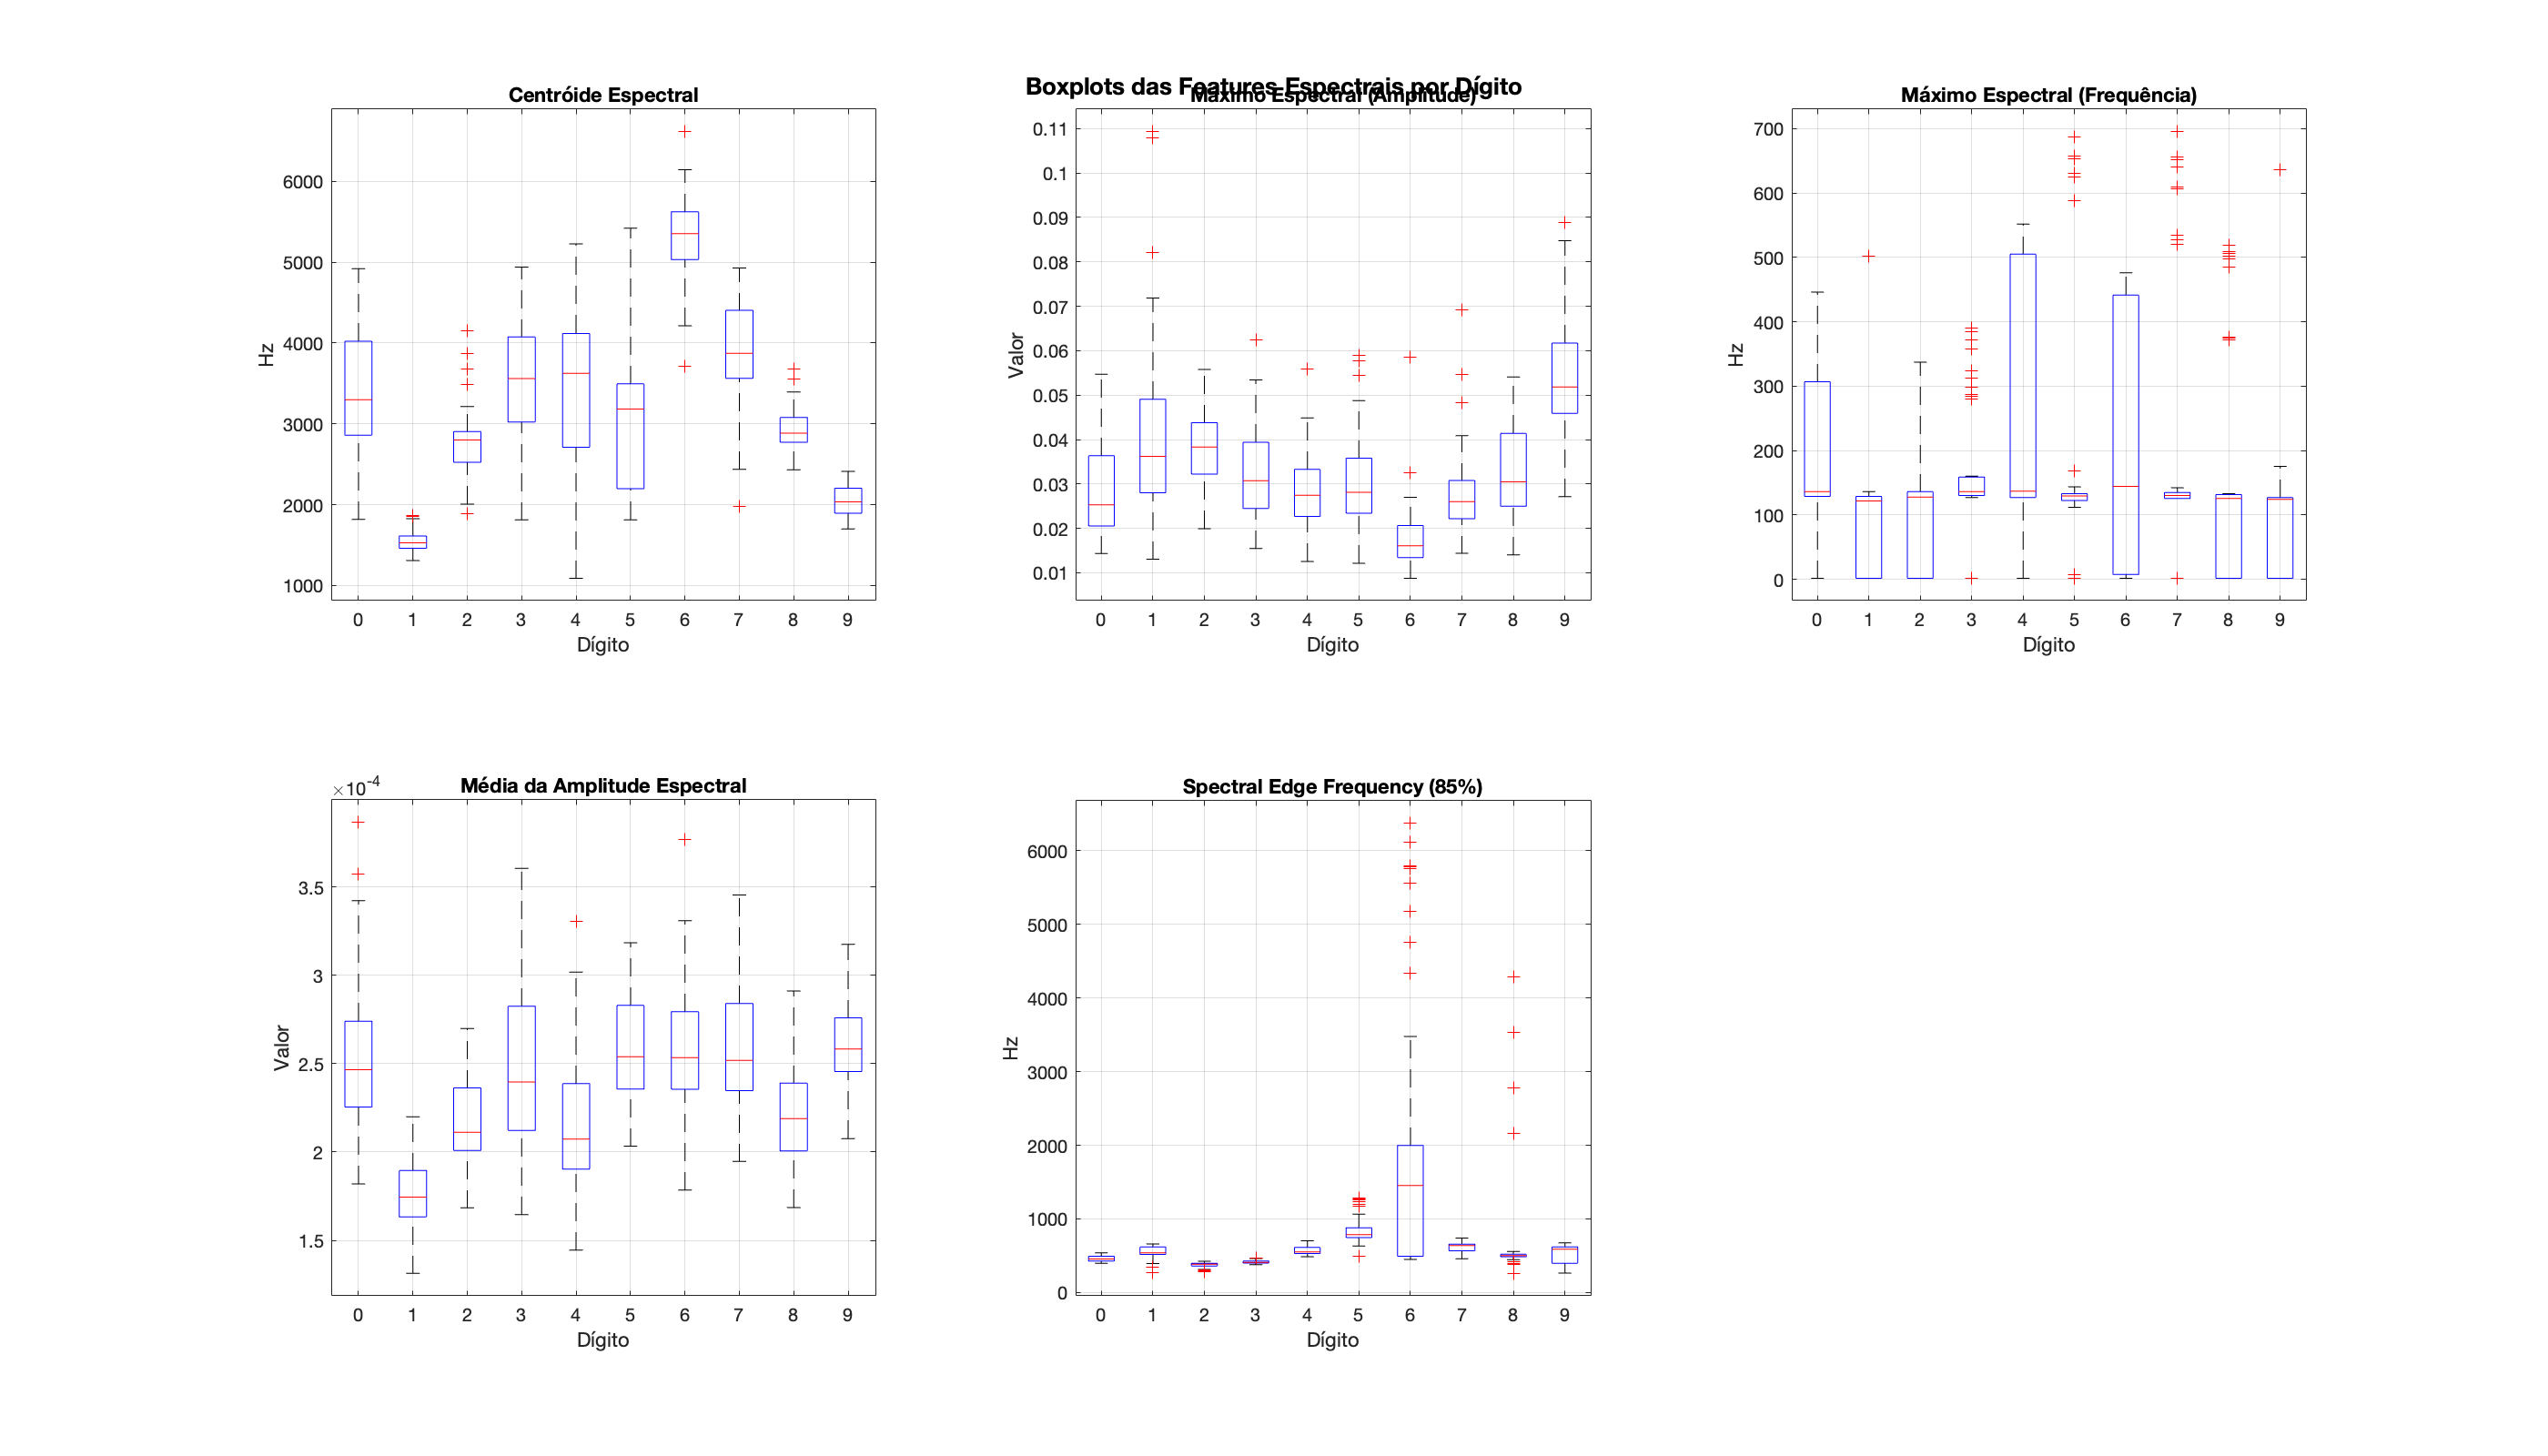


figure('Name','Boxplots - Todas as Features Espectrais', ...
       'NumberTitle','off', 'Position',[50 50 1400 800]);
sgtitle('Boxplots das Features Espectrais por Dígito', 'FontSize',13, 'FontWeight','bold');

subplot(2,3,1); boxplot(T.FeatSpecCentroid, T.Digit); title('Centróide Espectral');          xlabel('Dígito'); ylabel('Hz'); grid on;
subplot(2,3,2); boxplot(T.FeatSpecMaxAmp,   T.Digit); title('Máximo Espectral (Amplitude)'); xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(2,3,3); boxplot(T.FeatSpecMaxFreq,  T.Digit); title('Máximo Espectral (Frequência)'); xlabel('Dígito'); ylabel('Hz'); grid on;
subplot(2,3,4); boxplot(T.FeatSpecMean,     T.Digit); title('Média da Amplitude Espectral'); xlabel('Dígito'); ylabel('Valor'); grid on;
subplot(2,3,5); boxplot(T.FeatSpecRolloff,  T.Digit); title('Spectral Edge Frequency (85%)'); xlabel('Dígito'); ylabel('Hz'); grid on;

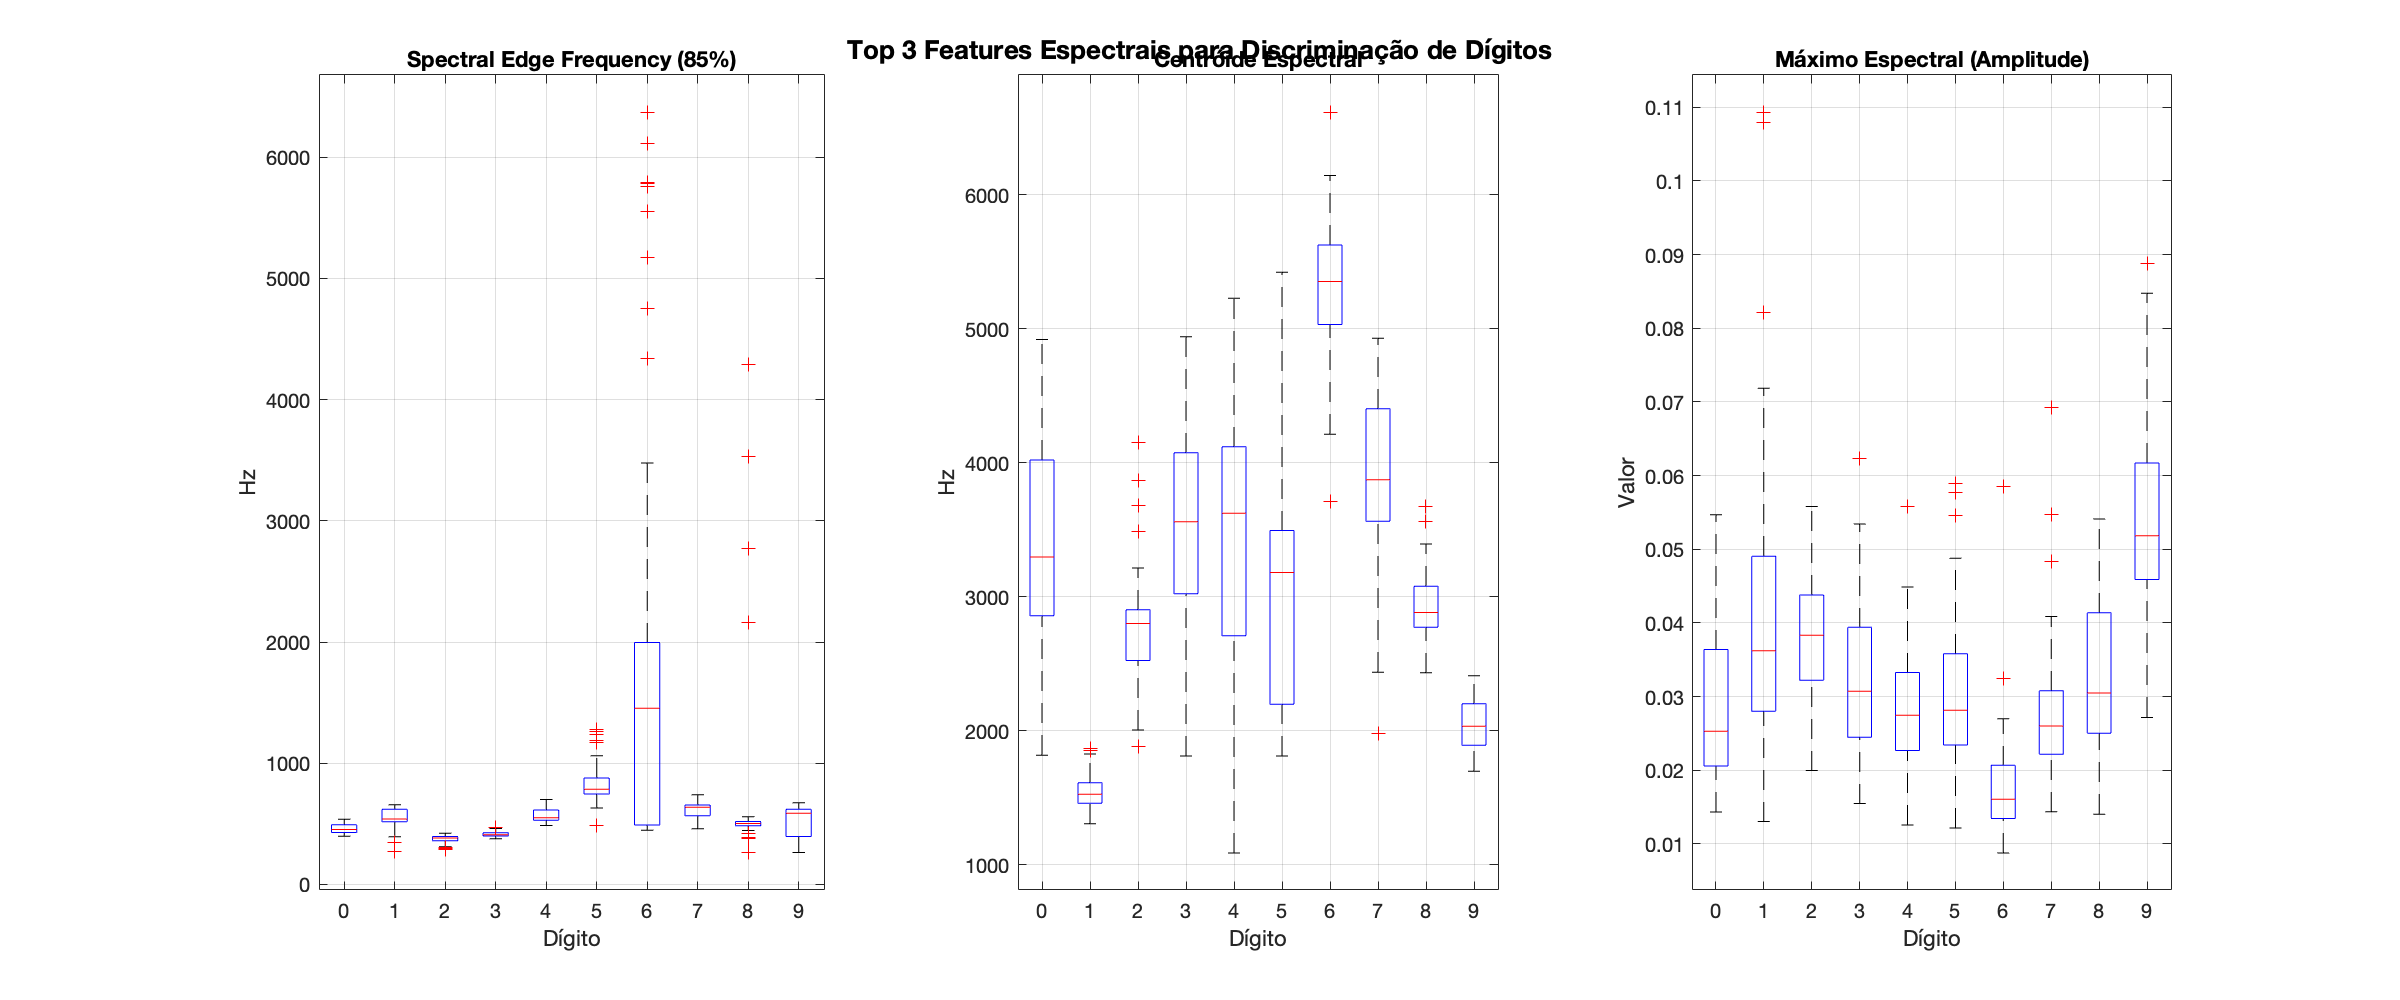


figure('Name','Boxplots - Top 3 Features Espectrais', ...
       'NumberTitle','off', 'Position',[50 50 1200 500]);
sgtitle('Top 3 Features Espectrais para Discriminação de Dígitos', 'FontSize',13, 'FontWeight','bold');

subplot(1,3,1); boxplot(T.FeatSpecRolloff,  T.Digit); title('Spectral Edge Frequency (85%)'); xlabel('Dígito'); ylabel('Hz'); grid on;
subplot(1,3,2); boxplot(T.FeatSpecCentroid, T.Digit); title('Centróide Espectral');            xlabel('Dígito'); ylabel('Hz'); grid on;
subplot(1,3,3); boxplot(T.FeatSpecMaxAmp,   T.Digit); title('Máximo Espectral (Amplitude)');   xlabel('Dígito'); ylabel('Valor'); grid on;


fprintf('  Features seleccionadas (top 3):\n');

  Features seleccionadas (top 3):


fprintf('  1. Spectral Edge Frequency – "six" completamente separado dos restantes.\n');

  1. Spectral Edge Frequency – "six" completamente separado dos restantes.


fprintf('     A fricativa "s" empurra muita energia para as altas frequencias.\n');

     A fricativa "s" empurra muita energia para as altas frequencias.


fprintf('  2. Centroide Espectral     – "one" claramente o mais baixo (~1500 Hz); "six" o mais alto (~5000 Hz).\n');

  2. Centroide Espectral     – "one" claramente o mais baixo (~1500 Hz); "six" o mais alto (~5000 Hz).


fprintf('  3. Maximo Espectral (Amp)  – "six" tem amplitude de pico visivelmente mais baixa.\n\n');

  3. Maximo Espectral (Amp)  – "six" tem amplitude de pico visivelmente mais baixa.




%% ================================================================
%  PONTO 13 – Limpeza e Gravação dos Dados
% ================================================================
fprintf('=== PONTO 13: Limpeza e Gravação (Meta 1) ===\n');

=== PONTO 13: Limpeza e Gravação (Meta 1) ===



T.Signal = [];
save('dados_meta1.mat', 'T', '-v7.3');
fprintf('  Sinais importados removidos da tabela.\n');

  Sinais importados removidos da tabela.


fprintf('  Tabela guardada em "dados_meta1.mat".\n');

  Tabela guardada em "dados_meta1.mat".


fprintf('  FIM DA META 1.\n\n');

  FIM DA META 1.




%% ================================================================
%  FUNÇÕES LOCAIS – OBRIGATORIAMENTE NO FINAL DO FICHEIRO
% ================================================================



function sig_out = remove_silence(sig, fs, window_ms, thresh)
% Remove o silêncio inicial com base na energia por janelas.
% Divide o sinal em janelas de window_ms ms e encontra a primeira
% janela cuja energia ultrapassa thresh*max_energia (onset da fala).
    % window_ms/1000 converte ms para segundos, *fs converte segundos para amostras
    win_samples = round(fs * window_ms / 1000);
    n_frames    = floor(numel(sig) / win_samples);

    if n_frames == 0, sig_out = sig; return; end

    energies = zeros(n_frames, 1);
    for k = 1:n_frames
        frame       = sig((k-1)*win_samples+1 : k*win_samples);
        energies(k) = sum(frame .^ 2);
    end

    max_e = max(energies);
    if max_e == 0, sig_out = sig; return; end

    onset = find(energies / max_e > thresh, 1, 'first');
    if isempty(onset), sig_out = sig; return; end

    sig_out = sig((onset-1)*win_samples+1 : end);
end


function sig_out = norm_amplitude(sig)
% Normaliza o sinal para [-1, 1] com base na amplitude máxima e mínima.
% min(sig) -> -1  e  max(sig) -> +1
    mn = min(sig);
    mx = max(sig);
    if mx == mn, sig_out = zeros(size(sig)); return; end
    sig_out = 2 * (sig - mn) / (mx - mn) - 1;
end


function sig_out = pad_trim(sig, target_len)
% Se o sinal for maior que target_len, corta. Se for menor, adiciona zeros no final.
    if numel(sig) >= target_len
        sig_out = sig(1:target_len);
    else
        sig_out = [sig; zeros(target_len - numel(sig), 1)];
    end
end


function dur = compute_duration(sig, fs, window_ms, thresh)
% Calcula a duração da fala em segundos: do primeiro ao último frame activo.
% Um frame é "activo" se a sua energia normalizada ultrapassa thresh.
% Isto remove tanto o silêncio inicial como o silêncio final.
    win_samples = round(fs * window_ms / 1000);
    n_frames    = floor(numel(sig) / win_samples);

    if n_frames == 0, dur = 0; return; end

    energies = zeros(n_frames, 1);
    for k = 1:n_frames
        frame       = sig((k-1)*win_samples+1 : k*win_samples);
        energies(k) = sum(frame .^ 2);
    end

    max_e = max(energies);
    if max_e == 0, dur = 0; return; end

    active = energies / max_e > thresh;
    first  = find(active, 1, 'first');
    last   = find(active, 1, 'last');

    if isempty(first), dur = 0; return; end

    % Duração em segundos entre o início do primeiro e o fim do último frame activo
    dur = (last - first + 1) * win_samples / fs;
end
